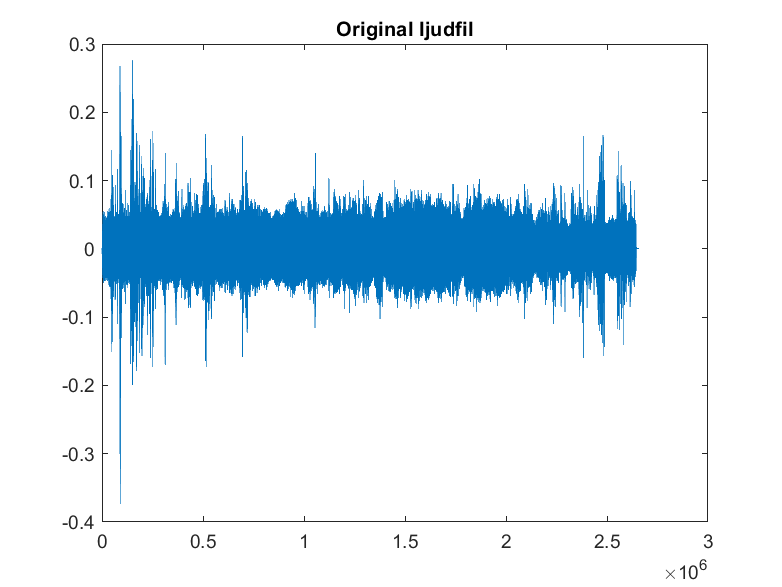

[y, Fs] = audioread('forensisktljud_og.wav');

copy_forensisktljud = (y(:, 1) + y(:, 2)) / 2;
copyA_fl = transpose(copy_forensisktljud);

% Plotta originalljudet
plot(copyA_fl);
title('Original ljudfil')

% ---- Ljudklipp av orginial ljudet ---- %
%ohorbart_kopare = y(2*Fs:9*Fs);     % Vad köparen ska köpa
ohorbart_kopare = y(10*Fs:20*Fs);  % Vad apparaterna gör/är?

brum_ljud = y(33*Fs:40*Fs);
%brum_ljud2 = y(41*Fs:45*Fs);

% ---- Hög- och lågpassfiltrering av ljudklipp ---- % 
cutFreqHigh = 85; % För en mansröst
cutFreqLow = 8000; % För en mansröst

ohorbart_kopare = highpass(ohorbart_kopare, cutFreqHigh, Fs);
ohorbart_kopare = lowpass(ohorbart_kopare, cutFreqLow, Fs);

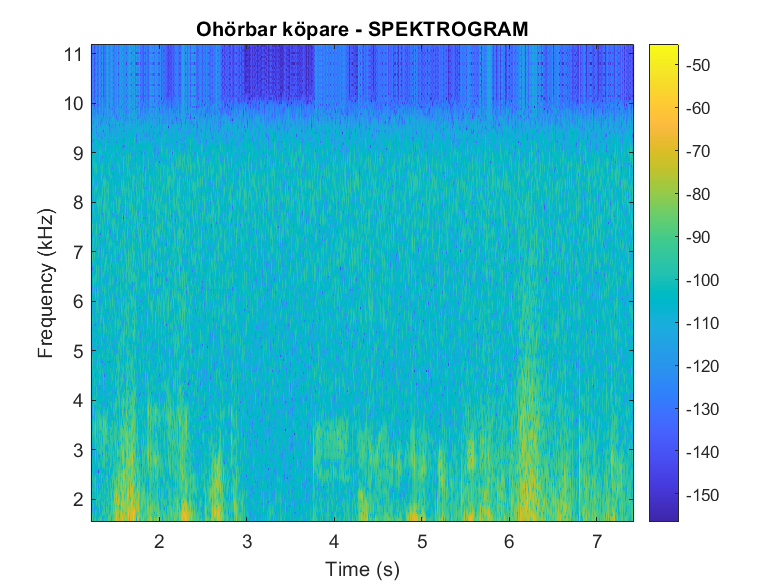

% ---- Spektogram ---- %
spectrogram(ohorbart_kopare, 400, 100, 1000 , Fs, 'yaxis');
ylim([0, 6])
title('Ohörbar köpare - SPEKTROGRAM')
colorbar;

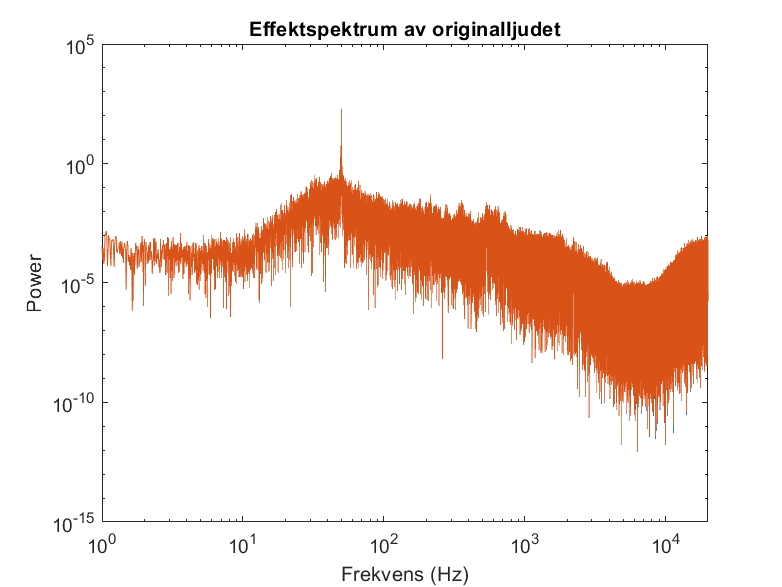

% ---- Fourier transform ---- %
% Originalljud
m = length(y);
n = pow2(nextpow2(m));
fft_Of_og = fft(y,n);
power = fft_Of_og.*conj(fft_Of_og)/n;
f = (0:n-1)*(Fs/n);
loglog(f,power);

xlim([1,20000]);
ylabel('Power');
xlabel('Frekvens (Hz)');
title('Effektspektrum av originalljudet');

% ---- Bandpassfiltrering (Butter) ----
orderOfFilter = 8; % Filterordning 
f_undre = 400;
f_ovre = 5000;
Wn = [f_undre / (Fs/2), f_ovre / (Fs/2)]; % Skärningsfrekvenser 
[b, a] = butter(orderOfFilter, Wn, 'bandpass');

ohorbart_kopare = filter(b, a, ohorbart_kopare);

ohorbart_kopare = ohorbart_kopare.*10; % Förstärkning av ljud
%sound(ohorbart_kopare, Fs);

% ---- Brusreducering med sgolayfilt() ----
order = 4; % Måste vara mindre än fönsterbredden 
framelen = 53; % (Fönsterbredd) Måste vara udda
ohorbart_kopare_noNoise = sgolayfilt(ohorbart_kopare, order, framelen);
%sound(ohorbart_kopare_noNoise, Fs);

% ---- Compression av originalljudet ---- (Blir väldigt dåligt efter kompression)
% compressionFactor = 2; % Justera kompressionsgraden efter behov
% for i = 1:length(ohorbart_kopare_noNoise)
%     % Applicera kompression
%     if ohorbart_kopare_noNoise(i) >= 0
%         ohorbart_kopare_noNoise(i) = ohorbart_kopare_noNoise(i) * (2 - ohorbart_kopare_noNoise(i));
%     else
%         ohorbart_kopare_noNoise(i) = ohorbart_kopare_noNoise(i) * (-2 - ohorbart_kopare_noNoise(i));
%     end
% end
% 
% % Normalisera ljudet efter kompression
% maxAmp = max(abs(ohorbart_kopare_noNoise));
% ohorbart_kopare_compressed = ohorbart_kopare_noNoise / maxAmp;
% 
% plot(ohorbart_kopare_compressed);
% title('Compression av testljud');
% sound(ohorbart_kopare_compressed, Fs);


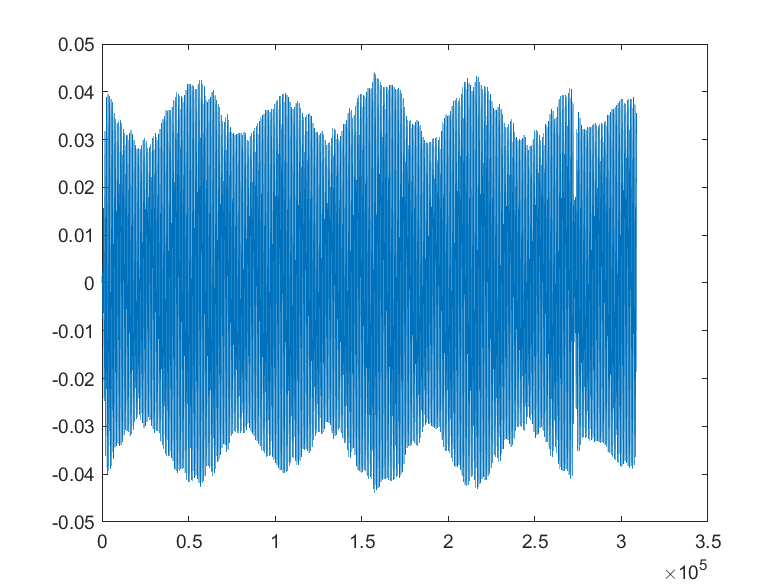

% ---- Brumljuds isolering ---- %

Wn = [40 , 60]/(Fs/2);
[b, a] = butter(2,Wn,'bandpass');
brum_ljud_isolerat = filter(b, a, brum_ljud);

% --- Plottar ljudvågen ---- %

% EFFEKTSPEKTRUM %
% m = length(brum_ljud_isolerat);
% n = pow2(nextpow2(m));
% fft_Of_brum = fft(brum_ljud_isolerat, n);
% power = fft_Of_brum.*conj(fft_Of_brum)/n;
% f_brum = (0:n-1)*(Fs/n);
% loglog(f_brum,power);
% 
% xlim([1,2000]);
% ylabel('Power');
% xlabel('Frekvens (Hz)');
% title('Effektspektrum av brumljudet');
% 
% title('Brumljudet - SPEKTROGRAM')
% colorbar;

plot(brum_ljud_isolerat); % Klippning i ljudet kan ses i vanliga plotten när jordbrummet är isolerat